
J = 0.2;   
b = 0.7;    
Kg = 0.4;  
Kt = 0.1; 
Ra = 10;     
La = 1;   

% Matrizes de estados
A = [-b/J, Kt/J; -Kg/La, -Ra/La]  

A =    -3.5000    0.5000
   -0.4000  -10.0000



B = [0; 1/La]  

B =      0
     1



C = eye(2)    

C =      1     0
     0     1


D = [0; 0]     

D =      0
     0



% Matriz de Controlabilidade
contr_mtz = ctrb(A, B)

contr_mtz =          0    0.5000
    1.0000  -10.0000



detcontr_mtz = det(contr_mtz)

detcontr_mtz = -0.5000


rank_contr = rank(contr_mtz);

% Verifica se o sistema é controlável
if rank_contr == size(A, 1)
    rank_contr
    disp('O sistema é controlável pelo rank de controlabildiade.');
else
    rank_contr
    disp('O sistema não é controlável pelo rank de controlabildiade.');
end

rank_contr = 2

O sistema é controlável pelo rank de controlabildiade.


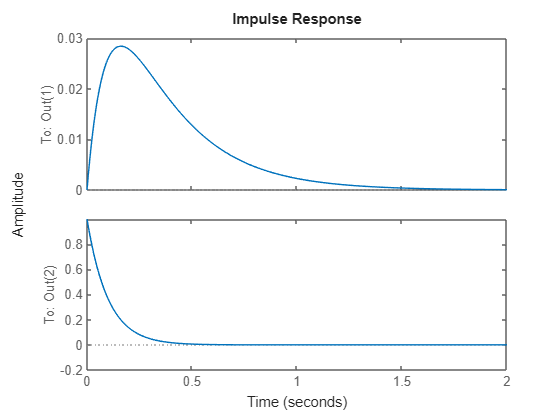


sys = ss(A, B, C, D);

% Resposta Impulsiva
impulse(sys)

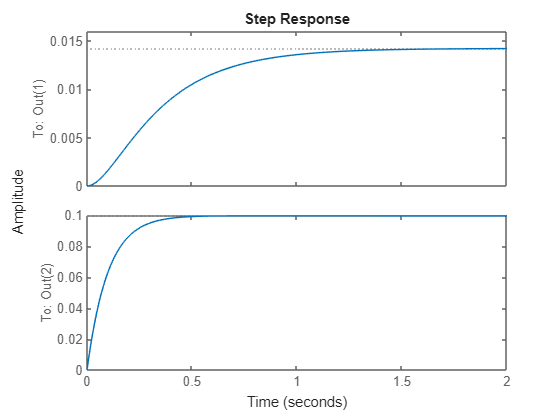


% Resposta à Entrada Degrau
step(sys)


% Regulaçao
desired_poles_reg = [-5, -6];  

%Determinação dos ganhos k1 e k2 de regulação
K_reg = acker(A, B, desired_poles_reg); %
k1_reg = K_reg(1);
k2_reg = K_reg(2);

% Sistema Regulado
An_reg = A - B * K_reg;
sys_reg = ss(An_reg, B, C, D);

% Condições iniciais [ia; ω]
x0 = [105; 0];  

syms k1 k2 h
K = [k1, k2];

% Altera C para rastrear apenas a saída desejada 
C_rastreio = [1, 0];  % Seleciona apenas a saída w (velocidade angular)

% Determina a nova matriz A de rastreio
An = [A - B * K, B * h; -C_rastreio, 0];

% Determina os autovalores
autoVal = eig(An);

% Associa as equações dos autovalores aos valores dos polos desejados
autoVal = [autoVal(1) == -5, autoVal(2) == -7, autoVal(3) == -9];

% Pede para ele resolver as equações, como um sistema de equações
kras = solve(autoVal(1), autoVal(2), autoVal(3));


% Traduz os resultados para o controlador de rastreio
k1_rastreio = double(kras.k1(1))

k1_rastreio = 163.1000

k2_rastreio = double(kras.k2(1))

k2_rastreio = 7.5000

h_rastreio = double(kras.h(1))

h_rastreio = 630